
clear


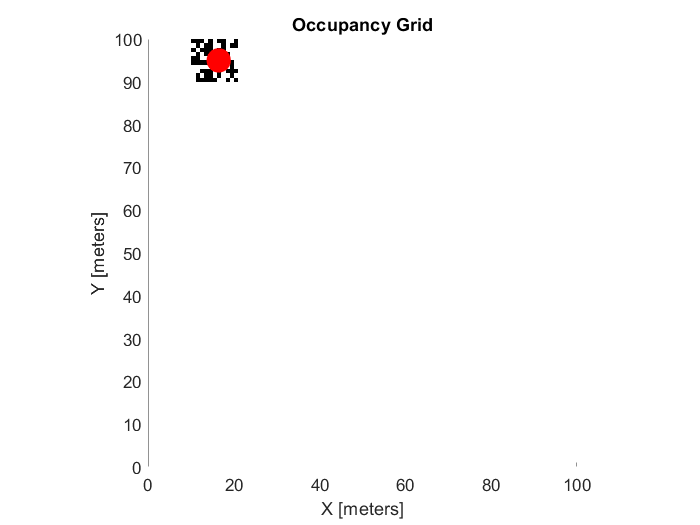

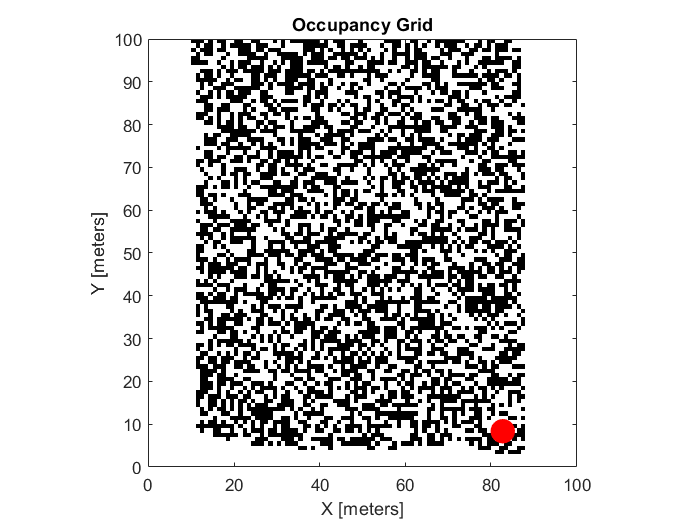

map = randi([0 1], 100, 100, "double");
drone = Drone(map, 15, 5, 7);
sensingDistance = 3;
mapWidth = 100;
mapHeight = 100; 
navigating = true;

targetX = [15];
targetY = [5];

xMove = mapWidth - 30;
yMove = sensingDistance*2;

direction = 'r';

poses = [15,5];
hold on

while navigating == true
    
    if direction == 'r'
        targetX = targetX + xMove;
        direction = 'l';
    else
        targetX = targetX - xMove;
        direction = 'r';
    end     
    
    while ~drone.isNear(targetX,targetY)
        drone = drone.navigateToPoint(targetX,targetY);
        drone.plot();
        pause(0.2);
        poses(end+1,:) = [drone.X, size(map,1) - drone.Y];
    end
    
    targetY = targetY + yMove; 
    while ~drone.isNear(targetX,targetY)
        drone = drone.navigateToPoint(targetX,targetY);
        drone.plot();
        pause(0.2);
        poses(end+1,:) = [drone.X, size(map,1) - drone.Y];
    end
    
    if targetY >= (mapHeight - yMove)
        navigating = false;
       
    end
    
end

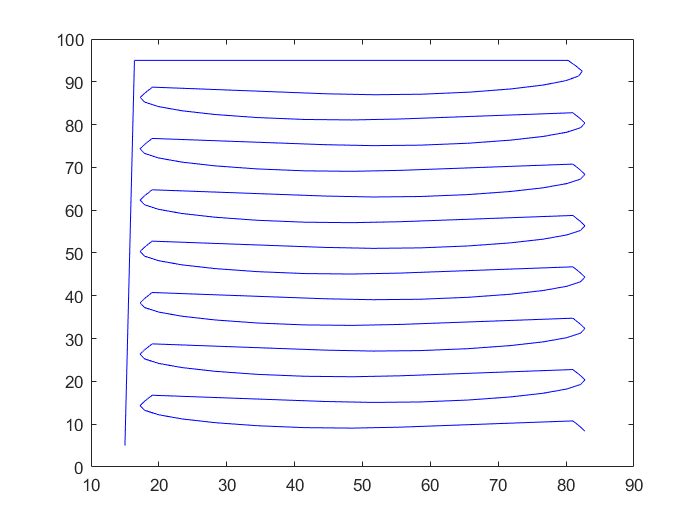

plot(poses(:,1),poses(:,2),"blue")

moves = drone.Moves

moves = 254

explored = length(drone.DroneMap(drone.DroneMap>0))

explored = 3705

total = size(drone.DroneMap, 1) * size(drone.DroneMap, 2)

total = 10000

percent = explored / total

percent = 0.3705